clear

addpath('matlab_functions\')

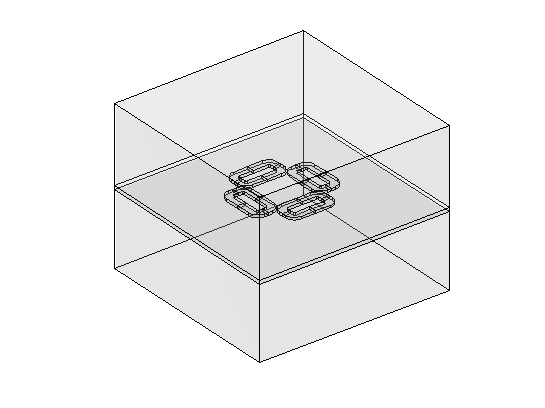

Model = myModel;
freq = 100; % (Hz)
mesh_size = 5; % 1:finest 9:coarsest

lim = 50e-3;
[x,y,z] = ndgrid( ...
    linspace(-lim, lim, 31), ...
    linspace(-lim, lim, 31), ...
    -2e-3);

Model = ComsolInterface('Build', Model);
ComsolInterface('PlotGeometry', Model);

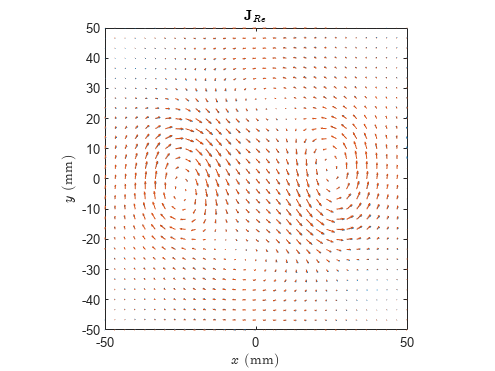

error: 13.122%


ComsolInterface('Solve', Model, freq, mesh_size);
[J1x,J1y] = ComsolInterface('InterpField', Model, {'Jx' 'Jy'}, x,y,z);

coilAbovePlate = CoilAbovePlate3D(Model.coil, Model.layers);
[J2x,J2y] = coilAbovePlate.EvaluateField({'Jx' 'Jy'}, x,y,z, 2*pi*freq);

CompareField(x,y, real(J1x),real(J1y), real(J2x),real(J2y), '$\textbf{J}_{Re}$')

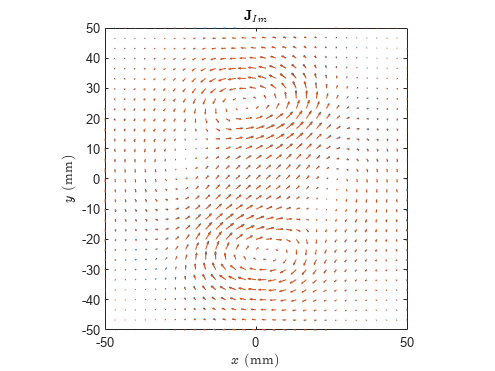

error: 17.8258%

CompareField(x,y, imag(J1x),imag(J1y), imag(J2x),imag(J2y), '$\textbf{J}_{Im}$')

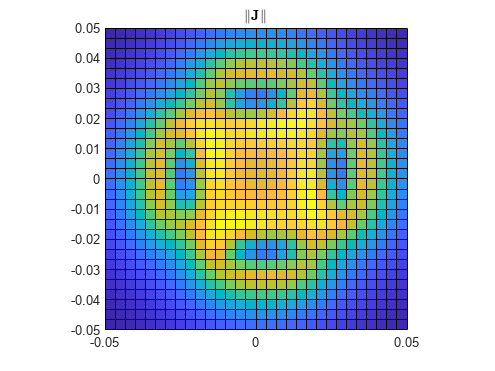


figure
pcolor(x, y, vecnorm(cat(3,J1x,J1y), 2, 3))
axis square
title('$\|\textbf{J}\|$', 'Interpreter','latex')

function CompareField(x,y, E1x,E1y, E2x,E2y, titlestr)

x_ = unique(x);
normE = vecnorm(cat(3, E1x, E1y), 2, 3);
scale = (x_(2) - x_(1)) * 1e3 / max(normE,[],'all');

figure
hold on
quiver(x*1e3, y*1e3, E1x*scale, E1y*scale, 'off')
quiver(x*1e3, y*1e3, E2x*scale, E2y*scale, 'off')
xlim([min(x,[],'all') max(x,[],'all')] * 1e3)
ylim([min(y,[],'all') max(y,[],'all')] * 1e3)
axis square
box on
title(titlestr, 'Interpreter','latex')
xlabel('$x$ (mm)', 'Interpreter','latex')
ylabel('$y$ (mm)', 'Interpreter','latex')

error = sqrt((E1x-E2x).^2 + (E1y-E2y).^2);
base = sqrt(E1x.^2 + E1y.^2);

fprintf("error: %g%%", mean(error) / mean(base) * 100)

end